clear
% Specify the file path of the multi-page TIFF
%test JC
tic
load('/Users/platel/Library/CloudStorage/GoogleDrive-jcplatel@gmail.com/Mon Drive/barrel/sofia/suite2p_ani65/suite2p/plane0/Fall.mat')

% 
% path='/Users/platel/Library/CloudStorage/GoogleDrive-jcplatel@gmail.com/Mon Drive/barrel/sofia/P0-P1/emx1/ani19_2022-01-21_b/';
% name='mot_corr_concat_downs_5.74_10_um.tif';
name='suite2p_ani65'

%load data and create analysis folder
%file_path='/Users/platel/Desktop/exp/Sofia/mc_tiff_downs_6.5_10_um.tif';
%path='/Users/platel/Desktop/exp/Sofia/';
% name='mc_tiff_downs_6.5_10_um.tif';
% name='ani18P3P4mc_tiff_downs_5.74_10_um.tif'


PathSave='/Users/platel/Desktop/exp/analysis/';

filename=[path name];
daytime = datestr(now,'yy_mm_dd_HH_MM_SS');
namefull=[PathSave daytime name '/'];
mkdir (namefull)    % make folder for saving analysis
disp(['make new folder ' namefull])

calcium=uint16(ops.refImg);
red=uint16(ops.meanImg_chan2_corrected);
frame_rate=30;
size_pixel=1.469;


 % write color code
 colors = [
    1 0 0;     % Red
    0 1 0;     % Green
    0 0 1;     % Blue
    1 1 0;     % Yellow
    1 0 1;     % Magenta
    0 1 1;     % Cyan
    0.5 0 0;   % Maroon
    0 0.5 0;   % Olive
    0 0 0.5;   % Navy
    0.5 0.5 0; % Olive Green
    0.5 0 0.5; % Purple
    0 0.5 0.5; % Teal
    0.75 0 0;  % Dark Red
    0 0.75 0;  % Lime Green
    0 0 0.75;  % Dark Blue
    0.75 0.75 0; % Dark Yellow
    0.75 0 0.75; % Dark Magenta
    0 0.75 0.75; % Dark Cyan
];


Fluo=F;
F=Fluo(iscell(:,1)>0,:);
redcell1=redcell(iscell(:,1)>0,:);
%numredcell=redcell(:,1)>0.65;
[NCell, nt]=size(F);


%Fluo=double(reshape(intensity,6241,18000));
F=double(F);
F=F./median(F,2);
% speed =smoothdata(speed,'gaussian',50);

%bleaching correction
for k = 1:NCell
    F(k, :) = detrend(F(k,:),'Continuous',false);
end
% disp('bleaching correction')
%traces=Fluo;
% Savitzky-Golay filter
F = sgolayfilt(F',3,5)';
% intensity=cell2mat(image_data);


%test seqNMF
% Fr=double(F./median(F,2));
% Fr = sgolayfilt(Fr',3,7)';
% K = 10;
% L = 50;
% lambda =.005;
% [W, H, cost,loadings,power] = seqNMF(Tr1b,K,L,lambda)

% 
% plot (Fluo(100,:))
% hold on
% plot (traces(100,:))
% hold off

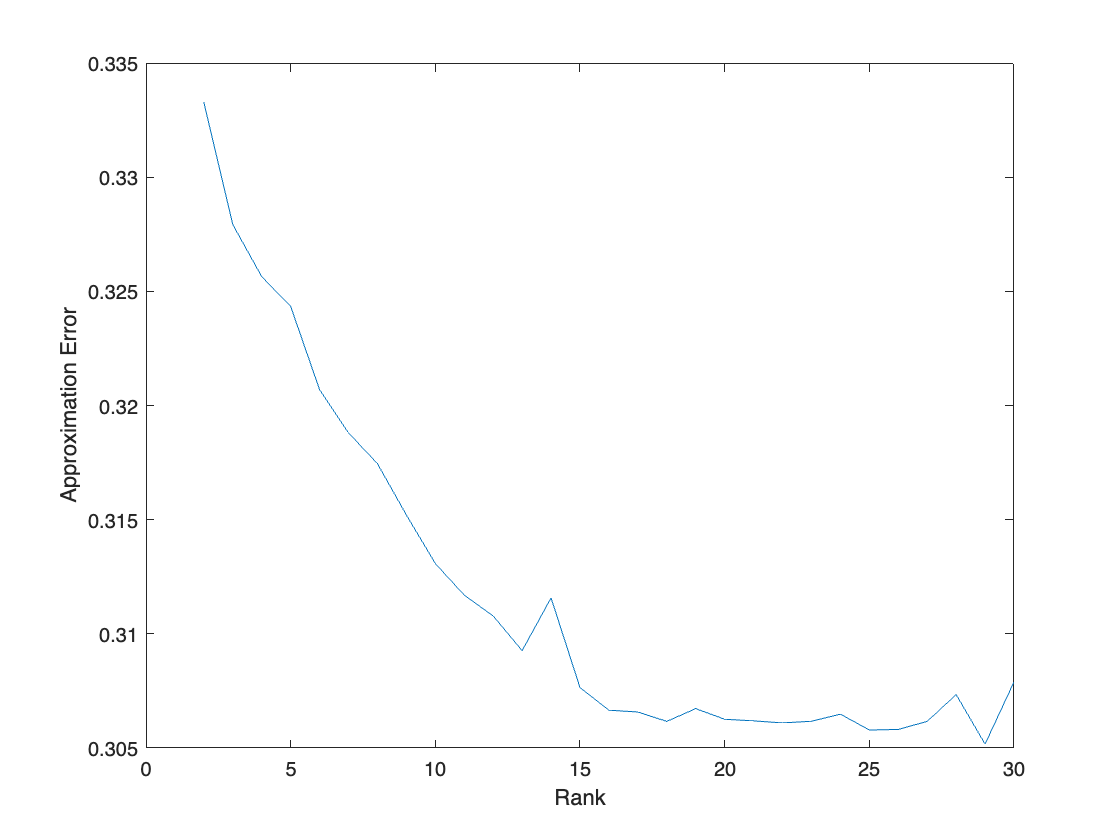

%approximation error to find number of K

num_iterations=1;
ranks = 2:30;
options = statset('UseParallel', true,'MaxIter',100);
aic_values = zeros(size(ranks));
bic_values = zeros(size(ranks));
%opt = statset('UseParallel',true,'Display','final');
% Calculate approximation error for each rank
%tic
errors = zeros(size(ranks));
for i = 1:length(ranks)
    [~,~,errors(i)] = nnmf(F, ranks(i), 'algorithm', 'als','replicates', num_iterations, 'options', options);
    % errors(i) = norm(F - Wtemp*H, 'fro')^2; % Frobenius norm (=euclidian
    % norm) what matlab calculate
    num_parameters = ranks(i)*size(F,2) + ranks(i)*size(F,1);
    aic_values(i) = 2*num_parameters + size(F,1)*size(F,2)*log(errors(i)/(size(F,1)*size(F,2)));
    bic_values(i) = num_parameters*log(size(F,1)*size(F,2)) + size(F,1)*size(F,2)*log(errors(i)/(size(F,1)*size(F,2)));
end

%Plot the approximation error
figure
plot(ranks, errors);
xlabel('Rank');
ylabel('Approximation Error');

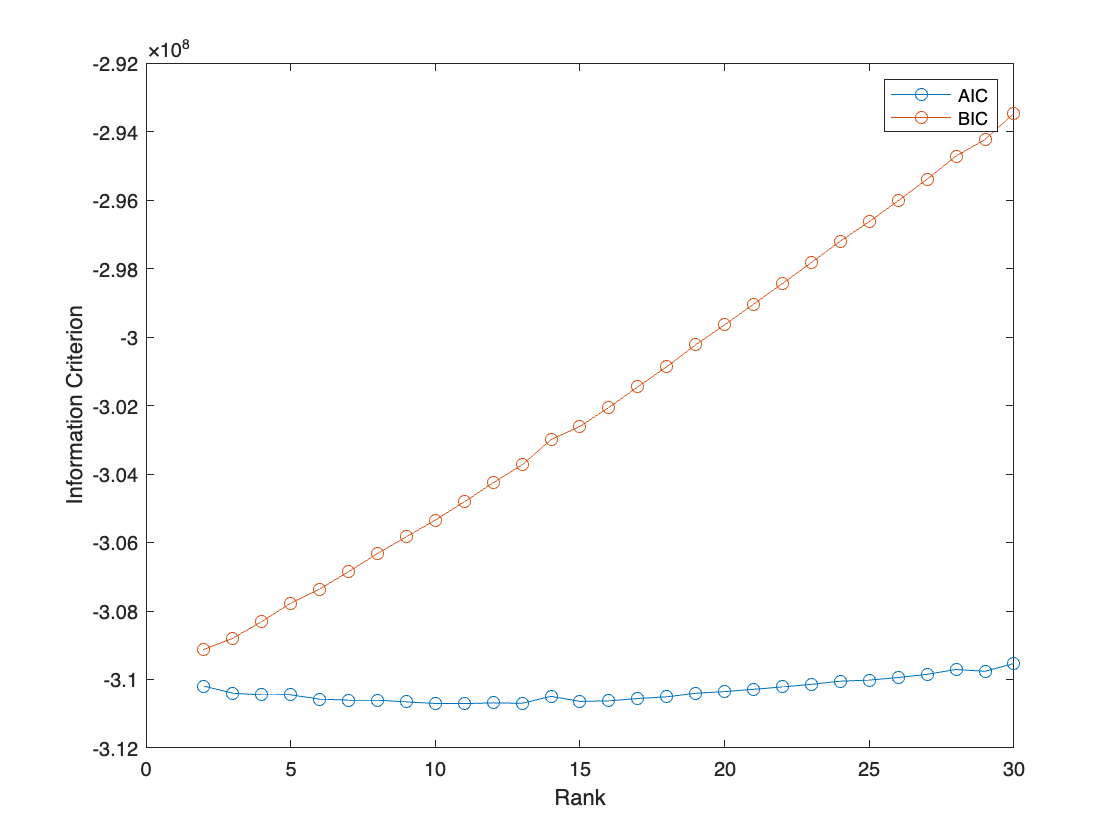


% Calculez la dérivée seconde de l'erreur par rapport à K
second_derivative = diff(diff(errors));
% Trouvez l'indice du point où la dérivée seconde change le plus brusquement
[~, optimal_K_index] = max(second_derivative);

optimal_K = ranks(optimal_K_index);
% 

figure
plot(ranks, aic_values, '-o');
hold on;
plot(ranks, bic_values, '-o');
xlabel('Rank');
ylabel('Information Criterion');
legend('AIC', 'BIC');

toc

Elapsed time is 12985.793403 seconds.



% Set parameters
tic
analysis_type='NMF_pixel';
num_components = 10;  % number of components to extract
num_iterations = 100;  % number of iterations for the NMF algorithm

% Perform NMF
options = statset('UseParallel', true,'MaxIter',100);

[W, H , D] = nnmf(F, num_components, 'algorithm', 'als', 'replicates', num_iterations, 'options', options);
toc

% Plot the NMF components
figure;

for i = 1:num_components

    subplot(num_components,1,i)
    % set(gcf,'position',[0,0,1200,200])
    bar(W(:,i));
    %title(['NMF Component ', num2str(i)]);
    axis ([0 NCell 0 max(W(:,1))])
    box off

    set(gca, 'XTickLabel', []);

end
exportgraphics(gcf,[namefull 'NMFcomponents.png'],'Resolution',300);

% Plot the temporal activation of the NMF components
figure;
for i = 1:num_components

    subplot(num_components,1,i)
    %set(gcf,'position',[0,0,1000,200]);
    plot(H(i,:));
    %title(['NMF Component ', num2str(i)]);
    %axis ([0 306 -0.04 0.5]);
    box off;
    set(gca, 'XTickLabel', []);
    % f=gcf;
    % x=SCE{:,i};
    % text(x,repmat(0.1,1,numel(x)),'*',"FontSize",8,"Color",'r')
end

exportgraphics(gcf,[namefull 'temporalcomponents.png'],'Resolution',300);


% measure frequency per component
freq_SCE=[];
for i=1:num_components    

    th(i)= 2*std(H(i,:)) ;

    [amplitude,locs] = findpeaks(H(i,:),'MinPeakProminence',th(i));
    SCE{i}=locs;
    % [amplitude,locs] = findpeaks(Tr1b(i,:),'MinPeakHeight',th(i),'MinPeakDistance',MinPeakDistance);
    % valeurs_identiques = intersect (locs,WinActive);
    % locs_sans_ide=setdiff(locs(:), valeurs_identiques);
    % Acttmp2{i}=locs_sans_ide;%%%%%%%%findchangepts(y,MaxNumChanges=10,Statistic="rms")
    % %Acttmp2{i}=locs;
    % ampli{i}=amplitude;
    freq_SCE(i)=numel(amplitude)/nt*frame_rate;
end
mean_freq_SCE=mean(freq_SCE);

%make real image of components

m=0;
NCell=sum(iscell(:,1)>0);

for n=1 : length(stat)

    if iscell(n,1)==1
        m=m+1;

        outline_gcampx(m)={double(stat{1, n}.xext+1)};
        outline_gcampy(m)={double(stat{1, n}.yext+1)};

        neuropil(m)={stat{1, n}.neuropil_mask};

        Coomasqx(m)={double(stat{1, n}.xpix+1)};%+1  to adpat suite2p output   ONLY 1 ??????
        Coomasqy(m)={double(stat{1, n}.ypix+1)};

    end

end


%show neurons and interneurons

figure
imagesc(red);
colormap (gray)
clim ([0 50])
hold on

for n=1:NCell

    x=cell2mat(outline_gcampx((n)));
    y=cell2mat(outline_gcampy((n)));
    % plot(x, y, '.', 'MarkerSize', 4,"Color",'w');

end


for n=1:NCell

    % x=cell2mat(Coomasqx(n));
    % y=cell2mat(Coomasqy(n));
  x=cell2mat(outline_gcampx((n)));
  y=cell2mat(outline_gcampy((n)));

    plot(x, y, '.', 'MarkerSize', 4,"Color",'g');
    if redcell1(n,2)>0.6
        plot(x, y, '.', 'MarkerSize', 4,"Color",'r');      
           % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
    end

end

axis image
axis off
hold off
title ('neurons and interneurons')
exportgraphics(gcf,[namefull 'map_neurons_interneurons.png'],'Resolution',300);


for i=1:num_components
    
    figure
    imagesc(calcium);
    colormap (gray)
    clim ([0 200])
    hold on
    for n=1:NCell
    
        x=cell2mat(outline_gcampx((n)));
        y=cell2mat(outline_gcampy((n)));
    
        %text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
        % plot(x, y, '.', 'MarkerSize', 4,"Color",'w');
    
    end
    
    thresholdW=std(W(:,i),1);
    for n=1:NCell
    
        if W(n,i)>thresholdW
            % x=cell2mat(Coomasqx(n));
            % y=cell2mat(Coomasqy(n));
            if redcell1(n,2)<0.65
                x=cell2mat(outline_gcampx((n)));
                y=cell2mat(outline_gcampy((n)));
                sorted_indices = convhull(x, y); 
                x = x(sorted_indices);
                y = y(sorted_indices);
        
                %text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
            
                %plot(x, y, '.', 'MarkerSize', 4,"Color",'g');
                % patch(x, y, 'r', 'FaceAlpha', 0.5);
                patch(x, y,colors(i,:),'FaceAlpha', 0.4)
            
            else
                % plot(x, y, '.', 'MarkerSize', 4,"Color",'r');
                patch(x, y,colors(i,:),'FaceAlpha', 0.4,'EdgeColor','w','LineWidth',2)
            end
    
        end

    end
    
    axis image
    axis off
    hold off
    title (['Component ' num2str(i)])
    exportgraphics(gcf,[namefull 'component_' num2str(i) '.tif'],'Resolution',300);

end




for deb=1:6%num_components-1

    for fin=deb+1:7%num_components
        figure
        imagesc(calcium);
        colormap (gray)
        clim ([0 200])
        hold on           
        for i=[deb fin]%num_components
            thresholdW=std(W(:,i),1);
            for n=1:NCell       
                if W(n,i)>thresholdW
                    % x=cell2mat(Coomasqx(n));
                    % y=cell2mat(Coomasqy(n));
                    if redcell1(n,2)<0.65
                        x=cell2mat(outline_gcampx((n)));
                        y=cell2mat(outline_gcampy((n)));
                        sorted_indices = convhull(x, y); 
                        x = x(sorted_indices);
                        y = y(sorted_indices);
                        %text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
                        %plot(x, y, '.', 'MarkerSize', 4,"Color",'g');
                        patch(x, y,colors(i,:),'FaceAlpha', 0.4)
                    else
                        % plot(x, y, '.', 'MarkerSize', 4,"Color",'r');
                        patch(x, y,colors(i,:),'FaceAlpha', 0.4,'EdgeColor','w','LineWidth',2)
                    end
                end
        
            end
        end
        axis image
        axis off
        hold off
        title (['component' num2str(deb) '-' num2str(fin) ])
        exportgraphics(gcf,[namefull 'component' num2str(deb) '-' num2str(fin) '.tif'],'Resolution',300);        
    end
end


%return



% assembly_sofia


save([namefull,'analysis_results.mat'])  
toc


%calculation area

% 
% area=zeros(num_components,1);
% for n=1:num_components
% 
%     for m=1:numObjects(n)
%         area(n)=region(m,n).Area+ area(n);
%     end
% 
%     area(n)=area(n)/ numObjects(n)*size_pixel^2;
% end
mean_area=0;
% mean_area=mean(area);


%export in excel 

daytime = datestr(now,'yy_mm_dd_HH_MM_SS');
%first file in same folder as experiment
pathexcel=[namefull '/analysis.xlsx'];
%
numline=2;
writematrix('date',pathexcel,'Range','A1');
writematrix (daytime,pathexcel,'Range','A2');
writematrix ('nom',pathexcel,'Range','B1');
writematrix (name,pathexcel,'Range','B2');

writematrix ('analysis',pathexcel,'Range','C1');
writematrix (analysis_type,pathexcel,'Range',['C' num2str(numline)]);

writematrix ('num components',pathexcel,'Range','D1');
writematrix (num_components,pathexcel,'Range',['D' num2str(numline)]);
writematrix ('num iteration',pathexcel,'Range','E1');
writematrix (num_iterations,pathexcel,'Range',['E' num2str(numline)]);
writematrix ('size pixel',pathexcel,'Range','F1');
writematrix (size_pixel,pathexcel,'Range',['F' num2str(numline)]);
writematrix ('mean area component',pathexcel,'Range','G1');
writematrix (mean_area,pathexcel,'Range',['G' num2str(numline)]);
writematrix ('mean_freq_SCE', pathexcel,'Range','H1');
writematrix (mean_freq_SCE, pathexcel,'Range','H2');  

writematrix ('all area', pathexcel,'Range','I1');
writematrix ('freq_SCE/compo', pathexcel,'Range','J1');
for n=1:num_components
   writematrix (area(n), pathexcel,'Range',['I' num2str(n+1)]);
   writematrix (freq_SCE(n), pathexcel,'Range',['J' num2str(n+1)]);
end
% writematrix (num2str(allarea), pathexcel,'Range','H2');


%writematrix (num2str(freq_SCE), pathexcel,'Range','J2');

% writematrix ('cell/assembly',pathexcel,'Range','I1');
% writematrix (idortho,pathexcel,'Range',['I' num2str(numline)]);
% writematrix ('assemblyraw',pathexcel,'Range','J1');
% writematrix (writeassemblyraw,pathexcel,'Range',['J' num2str(numline)]);
% writematrix ('cell/assemblyraw',pathexcel,'Range','K1');
% writematrix (idraw,pathexcel,'Range',['K' num2str(numline)]);
% writematrix ('assemblystat',pathexcel,'Range','L1');
% writematrix (writeassemblystat,pathexcel,'Range',['L' num2str(numline)]);
% writematrix ('cell/assemblystat',pathexcel,'Range','M1');
% writematrix (idstat,pathexcel,'Range',['M' num2str(numline)]);
% writematrix ('sequences',pathexcel,'Range','N1');
% writematrix ('no seq yet',pathexcel,'Range',['N' num2str(numline)]);
% writematrix ('Ncell',pathexcel,'Range','O1');
% writematrix (NCell,pathexcel,'Range',['O' num2str(numline)]);
% writematrix ('frames',pathexcel,'Range','P1');
% writematrix (length(Tr1b),pathexcel,'Range',['P' num2str(numline)]);
% writematrix ('sampling rate',pathexcel,'Range','Q1');
% writematrix (sampling_rate,pathexcel,'Range',['Q' num2str(numline)]);
% writematrix ('nb frame not running',pathexcel,'Range','R1');
% writematrix (length(WinRest),pathexcel,'Range',['R' num2str(numline)]);
% writematrix ('average speed',pathexcel,'Range','S1');
% writematrix (average_speed,pathexcel,'Range',['S' num2str(numline)]);
% writematrix ('sce_n_cells_threshold',pathexcel,'Range','T1');
% writematrix (sce_n_cells_threshold,pathexcel,'Range',['T' num2str(numline)]);
% writematrix ('n_kmean_surrogate',pathexcel,'Range','U1');
% writematrix (kmeans_surrogate,pathexcel,'Range',['U' num2str(numline)]);
% writematrix ('min_sce_distance',pathexcel,'Range','V1');
% writematrix (MinPeakDistancesce,pathexcel,'Range',['V' num2str(numline)]);
% writematrix ('MinPeakDistance',pathexcel,'Range','W1');
% writematrix (MinPeakDistance,pathexcel,'Range',['W' num2str(numline)]);
% writematrix ('synchronous_frames',pathexcel,'Range','X1');
% writematrix (synchronous_frames,pathexcel,'Range',['X' num2str(numline)]);
% writematrix ('percentile sce threshold',pathexcel,'Range','Y1');
% writematrix (percentile,pathexcel,'Range',['Y' num2str(numline)]);
% writematrix ('mini threshold activity detection',pathexcel,'Range','Z1');
% writematrix (minithreshold,pathexcel,'Range',['Z' num2str(numline)]);



% %here we write all experiments
% 
% pathexcel=[PathSave 'analysis_sofia_ALL.xlsx'];
% data =readcell(pathexcel);
% [row , col]=size (data);
% numline=row+1;
% 
% writematrix (daytime,pathexcel,'Range',['A' num2str(numline)]);
% writematrix (name,pathexcel,'Range',['B' num2str(numline)]);
% writematrix (analysis_type,pathexcel,'Range',['C' num2str(numline)]);
% writematrix (num_components,pathexcel,'Range',['D' num2str(numline)]);
% writematrix (num_iterations,pathexcel,'Range',['E' num2str(numline)]);
% writematrix (size_pixel,pathexcel,'Range',['F' num2str(numline)]);
% writematrix (mean_area,pathexcel,'Range',['G' num2str(numline)]);
% writematrix (allarea,pathexcel,'Range',['H' num2str(numline)]);
% % 
% % writematrix (daytime,pathexcel,'Range',['A' num2str(numline)]);
% % writematrix (identifier,pathexcel,'Range',['B' num2str(numline)]);
% % writematrix (session,pathexcel,'Range',['C' num2str(numline)]);
% % writematrix (NRace,pathexcel,'Range',['D' num2str(numline)]);
% % writematrix (freqsce,pathexcel,'Range',['E' num2str(numline)]);
% % writematrix (NRaceOK,pathexcel,'Range',['F' num2str(numline)]);
% % writematrix (freqsceok,pathexcel,'Range',['G' num2str(numline)]);
% writematrix (writeassemblyortho,pathexcel,'Range',['H' num2str(numline)]);
% writematrix (num2str(idortho),pathexcel,'Range',['I' num2str(numline)]);
% writematrix (writeassemblyraw,pathexcel,'Range',['J' num2str(numline)]);
% writematrix (num2str(idraw),pathexcel,'Range',['K' num2str(numline)]);
% writematrix (writeassemblystat,pathexcel,'Range',['L' num2str(numline)]);
% writematrix (num2str(idstat),pathexcel,'Range',['M' num2str(numline)]);
% writematrix ('no seq yet',pathexcel,'Range',['N' num2str(numline)]);
% writematrix (NCell,pathexcel,'Range',['O' num2str(numline)]);
% writematrix (length(F),pathexcel,'Range',['P' num2str(numline)]);
% writematrix (sampling_rate,pathexcel,'Range',['Q' num2str(numline)]);
% writematrix (Nz,pathexcel,'Range',['R' num2str(numline)]);
% writematrix (average_speed,pathexcel,'Range',['S' num2str(numline)]);
% writematrix (sce_n_cells_threshold,pathexcel,'Range',['T' num2str(numline)]);
% writematrix (kmeans_surrogate,pathexcel,'Range',['U' num2str(numline)]);
% writematrix (MinPeakDistancesce,pathexcel,'Range',['V' num2str(numline)]);
% writematrix (MinPeakDistance,pathexcel,'Range',['W' num2str(numline)]);
% writematrix (synchronous_frames,pathexcel,'Range',['X' num2str(numline)]);
% writematrix (percentile,pathexcel,'Range',['Y' num2str(numline)]);
% writematrix ('mini threshold activity detection',pathexcel,'Range','Z1');
% writematrix (minithreshold,pathexcel,'Range',['Z' num2str(numline)]);

save([namefull,'analysis_results.mat'])  
toc

Elapsed time is 11150.657522 seconds.


% % Define a range of ranks
% ranks = 6:15;
% num_iterations=10;
% tic
% % Calculate AIC(Akaike Information Criterion) and BIC(Bayesian Information Criterion) for each rank 
% aic_values = zeros(size(ranks));
% bic_values = zeros(size(ranks));
% for i = 1:length(ranks)
%     [W,H] = nnmf(F, ranks(i), 'algorithm', 'als','replicates', num_iterations, 'options', options);
%     rss = norm(F - W*H, 'fro')^2;
%     num_parameters = ranks(i)*size(F,2) + ranks(i)*size(F,1);
%     aic_values(i) = 2*num_parameters + size(F,1)*size(F,2)*log(rss/(size(F,1)*size(F,2)));
%     bic_values(i) = num_parameters*log(size(F,1)*size(F,2)) + size(F,1)*size(F,2)*log(rss/(size(F,1)*size(F,2)));
% end
% 
% % Plot AIC and BIC
% figure
% plot(ranks, aic_values, '-o');
% hold on;
% plot(ranks, bic_values, '-o');
% xlabel('Rank');
% ylabel('Information Criterion');
% legend('AIC', 'BIC');
% toc


%%%%%%cross validation%%%%%%%%%%% 
% Define the range of k values to test
% k_values = 1:20;  % Adjust the range as needed

% Specify the number of cross-validation folds
% num_folds = 5;    % You can change the number of folds
% % Initialize a cell array to store the cross-validation results
% cv_rmse = cell(length(k_values), num_folds);
% 
% % Perform k-fold cross-validation for each value of k
% for i = 1:length(k_values)
%     k = k_values(i);
% 
%     for fold = 1:num_folds
%         % Split your data into training and testing sets for this fold (e.g., using cvpartition or manually)
%         cv = cvpartition(size(F, 1), 'KFold', num_folds);
%         train_indices = training(cv, fold);
%         test_indices = test(cv, fold);
%         F_train = F(train_indices, :);
%         F_test = F(test_indices, :);
% 
%         % Perform NNMF on the training data with the current k
%         [W, H] = nnmf(F_train, k, 'options', options);
% 
%         % Reconstruct the test data with the same dimensions as F_test
%         F_test_reconstructed = W * H;
%         F_test_reconstructed = imresize(F_test_reconstructed, size(F_test));
% 
%         % Calculate RMSE for this fold
%         rmse = sqrt(mean((F_test - F_test_reconstructed).^2));
% 
%         % Store the RMSE in the cv_rmse cell array
%         cv_rmse{i, fold} = rmse;
%     end
% end
% 
% % Calculate the mean RMSE across all folds for each k
% mean_cv_rmse = zeros(length(k_values), 1);
% for i = 1:length(k_values)
%     rmse_values = cell2mat(cv_rmse(i, :)); % Convert cell array to matrix
%     mean_cv_rmse(i) = mean(rmse_values);
% end
% 
% % Find the optimal k (e.g., the one with the lowest mean RMSE)
% [optimal_k, idx] = min(mean_cv_rmse);
% 
% % Display the results
% fprintf('Optimal number of components (k) selected: %d\n', k_values(idx));

% return
% 
% nbassemblies=length(assemblyortho);
% n=1
% for n=1:nbassemblies
%    [subrow, subcol] = ind2sub([55, 55], assemblyortho{n}); 
% 
%    cellassembly{n,1} = subrow;
%    cellassembly{n,2} = subcol;
% end
% black=zeros(55,55)
% figure
% imagesc(black)
% colormap (gray)
% hold on

% for n=1:nbassemblies
%     x = cellassembly{n,1}; % X coordinates
%     y = cellassembly{n,2}; % Y coordinates
% 
%     % Combine x and y into a single matrix of points
%     points = [x', y'];
% 
%     % Find the convex hull of the points
%     k = convhull(points);
% 
%     % Sort the vertices in clockwise order
%     x_sorted = x(k);
%     y_sorted = y(k);
%     % plot (cellassembly{n,1},cellassembly{n,2},'.', 'MarkerSize', 30,"Color",colors(n,:))
%     patch (x_sorted,y_sorted,colors(n,:))
% end
% hold off
% % for n=2%:nbassemblies
% %     plot (cellassembly{n,1},cellassembly{n,2},'.', 'MarkerSize', 30,"Color",'r')
% % end
% % for n=3%:nbassemblies
% %     plot (cellassembly{n,1},cellassembly{n,2},'.', 'MarkerSize', 30,"Color",'g')
% % end


% figure
% imagesc(black)
% colormap (gray)
% hold on
% 
% for n=1:nbassemblies
% 
% 
%     plot (cellassembly{n,1},cellassembly{n,2},'.', 'MarkerSize', 30,"Color",colors(n,:))
% 
% end
% hold off

%measurement size assembly
% 
% for n=1:nbassemblies
% 
%    area_assembly(n)=length(assemblyortho{n})*size_pixel^2
% 
% end
% mean_area=mean(area_assembly)
% 